**Data import, Ropt = 5042 Ohm**

clear;
filename = 'Bender Solenoid test';
sheetname1 = 'Ropt = 5042';
data = readmatrix(filename,'Sheet',sheetname1);

**Power and Voltage output vs. disp**

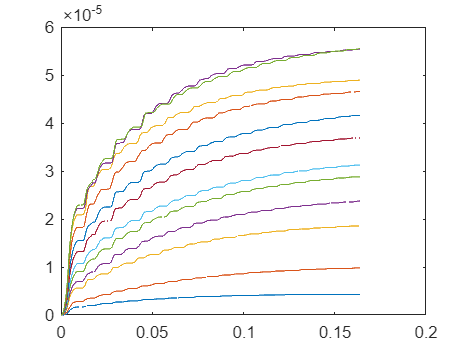

clf
Ropt = 5042; %[Ohm]
disp = data(7,1:10:end-9)*1e3; %[um]
Energy_all = zeros(1,size(data,2)/10);
Power_all = zeros(1,size(data,2)/10);
Energy_output_total = zeros(1,size(data,2)/10);
for i = 1:ceil(size(data,2)/10)
    [energy_avg, sum_Energy_avg, power_avg, time] = data2energyBenderRopt(data(:,10*i-9:10*i),Ropt); %at each R
    Energy_all(i) = sum_Energy_avg;
    Power_all(i) = power_avg;
    plot(time,energy_avg)
    hold on
end

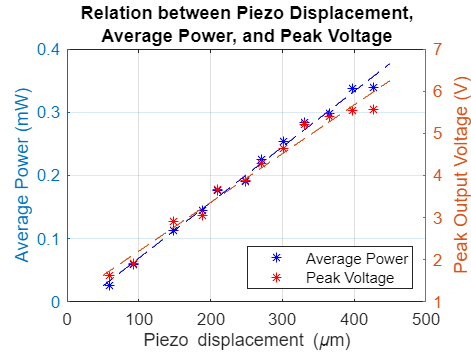

clf
[disp_sorted, idx] = sort(disp);
Power_all_sorted = Power_all(idx) .* 1e3; %Power output in [mW] unit
Energy_all_sorted = Energy_all(idx) .*1e3; %Energy output in [mJ] unit
volt_max = transpose(data(5,1:10:end-9));
volt_max_sorted = volt_max(idx);

%fit curve
yyaxis left;
load enso
Power_disp = fit(transpose(disp_sorted),transpose(Power_all_sorted),'poly1');
plot(transpose(disp_sorted),transpose(Power_all_sorted),'*b')
hold on
plot(Power_disp,'b')
hold off
ylabel('Average Power (mW)')
%ylim([0,2.5])

yyaxis right;
volt_disp = fit(transpose(disp_sorted),volt_max_sorted,'poly1');
plot(transpose(disp_sorted),volt_max_sorted,'*r')
hold on
plot(volt_disp,'')
hold off
ylabel('Peak Output Voltage (V)')
% ylim([0,2.5])

legend('Average Power','','Peak Voltage','','Location','southeast')
xlabel('Piezo displacement (\mum)')
title({'Relation between Piezo Displacement,';'Average Power, and Peak Voltage'})
grid on

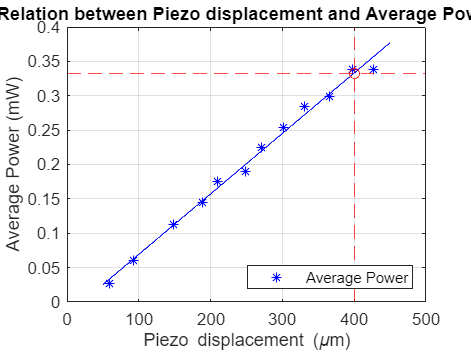

clf
%fit curve
Power_disp = fit(transpose(disp_sorted),transpose(Power_all_sorted),'poly1');
plot(transpose(disp_sorted),transpose(Power_all_sorted),'*b')
hold on
plot(Power_disp,'b')
plot(400,0.333,'or')
xline(400,'r--')
yline(0.333,'r--')
hold off
xlabel('Piezo displacement (\mum)')
ylabel('Average Power (mW)')
legend('Average Power','Location','southeast')
title('Relation between Piezo displacement and Average Power')
grid on

%ylim([0,2.5])

## **This part is for a presentation slide**

**Voltage-Time response at Ropt, d = **

% clf
% d = data(7,1:end-9:10);
% energy_pre_slide = [];
% for i = [5 8 12]
%     [energy_avg, sum_Energy_avg, power_avg, time] = data2energyBenderRopt(data(:,10*i-9:10*i),Ropt);
%     Energy_all(i) = sum_Energy_avg;
%     Power_all(i) = power_avg;
%     [voltage, time1] = dataCutOff(data(:,10*i-9:10*i));
%     if i == 5
%         subplot(3,1,3);
%         plot(time1,voltage,'Color','#0072BD')
%         grid on
%         hold on
%         xlabel('time (s)')
%         ylabel('Voltage (V)')
%         xlim([0,0.2])
%         d4 = num2str(data(7,10*i-9)*1e3) % disp in [um]
%         title(['Voltage response of Ropt at displacement = ' d4 ' \mum'])
% 
%     end
%     if i == 8
%         subplot(3,1,2);
%         plot(time1,voltage,'Color','#D95319')
%         grid on
%         hold on
%         xlabel('time (s)')
%         ylabel('Voltage (V)')
%         xlim([0,0.2])
%         d6 = num2str(data(7,10*i-9)*1e3) % disp in [um]
%         title(['Voltage response of Ropt at displacement = ' d6 ' \mum'])
%     end
%     if i == 12
%         subplot(3,1,1);
%         plot(time1,voltage,'Color','#EDB120')
%         grid on
%         hold on
%         xlabel('time (s)')
%         ylabel('Voltage (V)')
%         xlim([0,0.2])
%         d9 = num2str(data(7,10*i-9)*1e3) % disp in [um]
%         title(['Voltage response of Ropt at displacement = ' d9 ' \mum'])
%     end
%     energy_pre_slide = [energy_pre_slide;energy_avg];
% end
% hold off
% 
% figure;
% plot(time,energy_pre_slide*1e6,'-') % plot in [uJ]
% grid on
% xlabel('time (s)')
% ylabel('Energy (\muJ)')
% 
% title('Energy-time of Ropt at each displacement')
% title(legend([d4 '\mum'],[d6 '\mum'],[d9 '\mum'],'Direction','reverse','Location','eastoutside'),'Piezo bender displacement')